
clear ; 
clc ; 
close all

n = 100 ;%
EAD = 1 ;  %%EXPOSURE AT DEFAULT
LGD = 0.5 ; %LOSS GIVEN DEFAULT
Def_Prob = 0.05 ;  %DEFAULT PROBABILITY
rho = 0.1 ;       %%CORRELATION BETWEEN OBLIGORS 
                   % IN THE CREDIT PORTFOLIO

alpha_Range = 0:0.01:0.999 ; %RANGE OF ALPHA VALUES



# QUESTION 1A

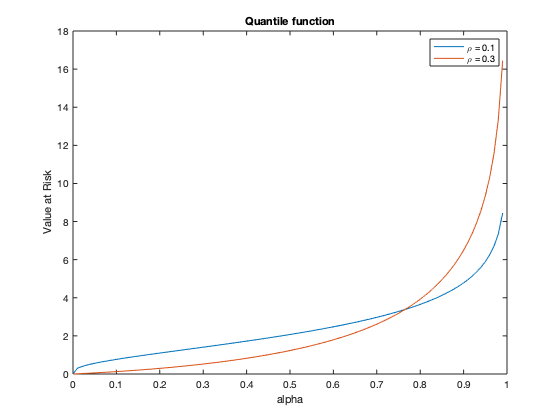


%%PLOTTING THE QUANTILE FUNCTION

nn = numel(alpha_Range) ;

V_1 = zeros(1,nn) ;
for i = 1:nn
    V_1(i) = Val_at_Risk(n, EAD, LGD, Def_Prob, rho , alpha_Range(i)) ;
end

rho2 = 0.3 ; % the second instance when rho = 30%

V_2 = zeros(1,nn) ;
for i = 1:nn
    V_2(i) = Val_at_Risk(n, EAD, LGD, Def_Prob, rho2 , alpha_Range(i)) ;
end


plot(alpha_Range,V_1)  
xlabel ('alpha')
ylabel ('Value at Risk')
hold on
plot(alpha_Range,V_2)
title('Quantile function')
legend('\rho = 0.1' , '\rho = 0.3')
hold off

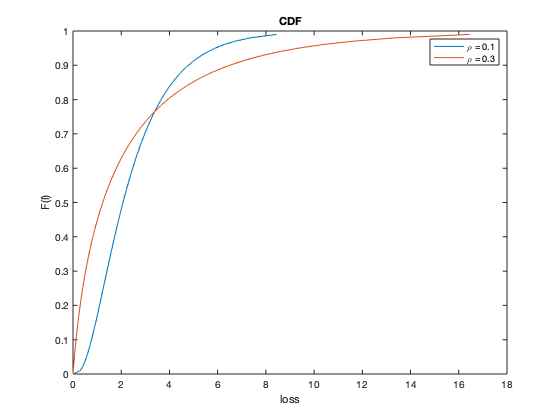

% PLOTTING THE CDF


plot(V_1,alpha_Range)  
xlabel ('loss')
ylabel ('F(l)')
hold on
plot(V_2,alpha_Range)
title('CDF')
legend('\rho = 0.1' , '\rho = 0.3')
hold off

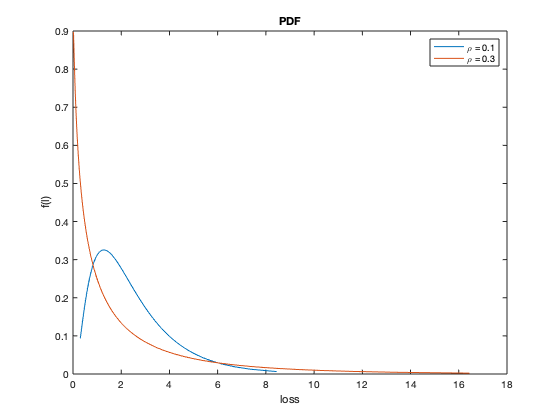


%% PLOTTING THE PDF
%nnn = numel(alpha_Range)

s2 = zeros(1,nn); % A vector of zeros that collects the 
                % pdfs for each level of alpha in the 
                % range defined above

for i = 1:nn
    f_1(i) = pdf(n, EAD, LGD, Def_Prob, rho , alpha_Range(i));
end

for i = 1:nn
    f_2(i) = pdf(n, EAD, LGD, Def_Prob, rho2 , alpha_Range(i));
end



plot(V_1,f_1)  
xlabel ('loss')
ylabel ('f(l)')
hold on
plot(V_2,f_2)
title('PDF')
legend('\rho = 0.1' , '\rho = 0.3')
hold off

# QUESTION 1B

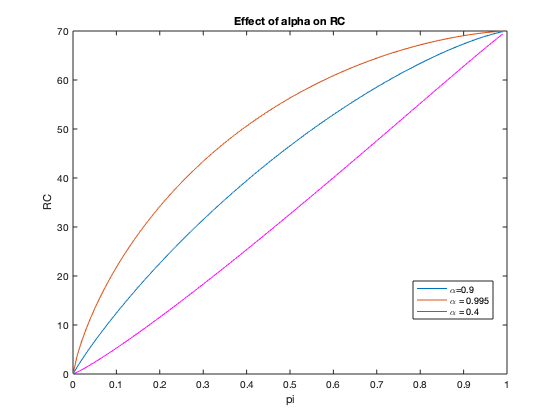

%RELATIONSHIP BETWEEN MY RISK CONTRIBUTION AND
%MODEL PARAMETERS; ALPHA


%alpha = 90%

EAD = 100;
LGD = 0.7;
Rho =0.2;
alpha_RC = 0.90;






PD = 0:0.01:0.999 ; 


v = numel(PD);

RC_1 = zeros(1,v);

for i = 1:v
    
    RC_1(i)= RC(EAD, LGD, PD(i), rho , alpha_RC);
end


%alpha = 99.5%

alpha_RC = 0.995;


RC_2 = zeros(1,v);

for i = 1:v
    RC_2(i)= RC(EAD, LGD, PD(i), rho , alpha_RC);
end


%alpha = 40%

alpha_RC = 0.4;
RC_3 = zeros(1,v);

for i = 1:v
    
    RC_3(i)= RC(EAD, LGD, PD(i), rho , alpha_RC);
end


plot(PD,RC_1)
hold on
plot(PD,RC_2)
hold on
plot(PD, RC_3,'m')
xlabel('pi')
ylabel('RC')
title('Effect of alpha on RC')
legend('\alpha=0.9','\alpha = 0.995','\alpha = 0.4','location',"best")
hold off

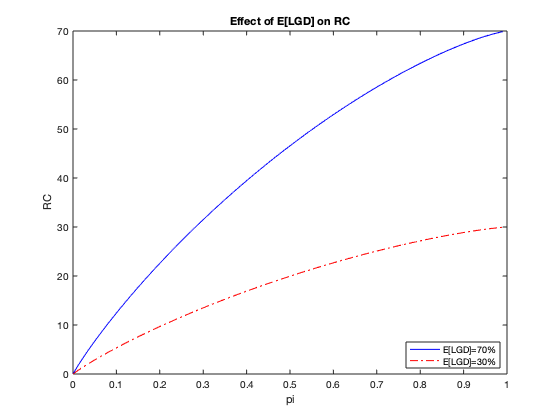


%RELATIONSHIP BETWEEN MY RISK CONTRIBUTION AND
%MODEL PARAMETERS; E[LGD]


%ELGD = 70%
EAD = 100;
LGD = 0.7;
Rho =0.1;
alpha_RC = 0.90;



PD = 0:0.01:0.999 ; 


v = numel(PD);

RC_R1 = zeros(1,v); %Risk contribution for rho=10%

for i = 1:v
    
    RC_R1(i)= RC(EAD, LGD, PD(i), rho , alpha_RC);
end




LGD  = 0.3;

RC_R2 = zeros(1,v); %Risk contribution for rho=30%

for i = 1:v
    
    RC_R2(i)= RC(EAD, LGD, PD(i), rho , alpha_RC);
end

plot(PD,RC_R1,'b')
hold on
plot(PD,RC_R2,'-.r')
xlabel('pi')
ylabel('RC')
title('Effect of E[LGD] on RC')
legend('E[LGD]=70%','E[LGD]=30%','location',"best")
hold off

%RELATIONSHIP BETWEEN MY RISK CONTRIBUTION AND
%MODEL PARAMETERS; Probability of default (PD)

%PD = 5%
EAD = 100;
LGD = 0.7;
alpha_RC = 0.90;
PD = 0.05

PD = 0.0500

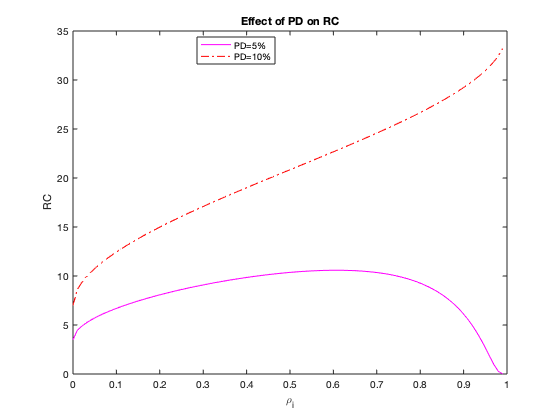



rho = 0:0.01:0.999 ; 
 

v = numel(rho);

RC_R1 = zeros(1,v); %Risk contribution for rho=10%

for i = 1:v
    
    RC_R1(i)= RC(EAD, LGD, PD, rho(i), alpha_RC);
end


%PD = 10%

PD  = 0.1;

RC_R2 = zeros(1,v); %Risk contribution for rho=30%

for i = 1:v
    
    RC_R2(i)= RC(EAD, LGD, PD, rho(i) , alpha_RC);
end

plot(rho,RC_R1,'m')
hold on
plot(rho,RC_R2,'-.r')
xlabel('\rho_i')
ylabel('RC')
title('Effect of PD on RC')
legend('PD=5%','PD=10%','location',"best")
hold off

%RELATIONSHIP BETWEEN MY RISK CONTRIBUTION AND
%MODEL PARAMETERS; Probability of default (PD)

%PD = 5%
EAD = 100;
LGD = 0.7;
alpha_RC = 0.99;
PD = 0.05

PD = 0.0500

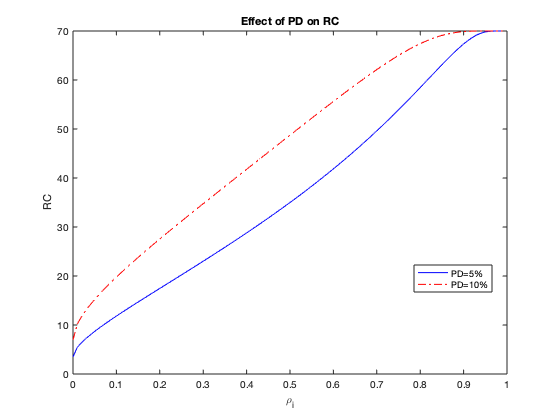



rho = 0:0.01:0.999 ; 
 

v = numel(rho);

RC_R1 = zeros(1,v); %Risk contribution for rho=10%

for i = 1:v
    
    RC_R1(i)= RC(EAD, LGD, PD, rho(i), alpha_RC);
end


%PD = 10%

PD  = 0.1;

RC_R2 = zeros(1,v); %Risk contribution for rho=30%

for i = 1:v
    
    RC_R2(i)= RC(EAD, LGD, PD, rho(i) , alpha_RC);
end

plot(rho,RC_R1,'b')
hold on
plot(rho,RC_R2,'-.r')
xlabel('\rho_i')
ylabel('RC')
title('Effect of PD on RC')
legend('PD=5%','PD=10%','location',"best")
hold off

# EXCERCISE 2

%%LGD

LGD_ARRAY = [0.68,0.9,0.22,0.45,0.17,0.25,0.89,0.65,0.75,0.56,0.87,0.92,0.46]

LGD_ARRAY =     0.6800    0.9000    0.2200    0.4500    0.1700    0.2500    0.8900    0.6500    0.7500    0.5600    0.8700    0.9200    0.4600



Mean_LGD_ARRAY = mean(LGD_ARRAY)

Mean_LGD_ARRAY = 0.5977

SD__LGD_ARRAY = std(LGD_ARRAY)

SD__LGD_ARRAY = 0.2702

alpha_hat = ((Mean_LGD_ARRAY^2*(1-Mean_LGD_ARRAY))/(SD__LGD_ARRAY^2))-Mean_LGD_ARRAY

alpha_hat = 1.3705

beta_hat =  ((Mean_LGD_ARRAY*(1-Mean_LGD_ARRAY)^2)/(SD__LGD_ARRAY^2))-(1-Mean_LGD_ARRAY)

beta_hat = 0.9225





% ALPHA = BETA

x_range = 0.00:0.01:0.999;

beta_alpha = 1

beta_alpha = 1


beta_beta  = 1

beta_beta = 1

 

u = numel(x_range);

beta_1 = zeros(1,u); %Risk contribution for rho=10%

for i = 1:u
    
    beta_1(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end


beta_alpha = 20

beta_alpha = 20


beta_beta  = 20

beta_beta = 20

 

u = numel(x_range);

beta_2 = zeros(1,u); %Risk contribution for rho=10%

for i = 1:u
    
    beta_2(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end




beta_alpha = 0.01

beta_alpha = 0.0100


beta_beta  = 0.01

beta_beta = 0.0100

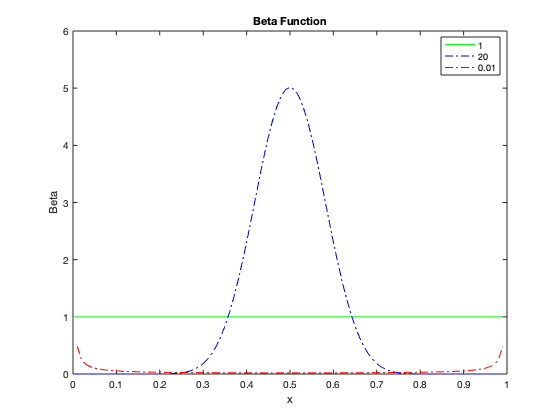

 

u = numel(x_range);

beta_3 = zeros(1,u); 

for i = 1:u
    
    beta_3(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end


plot(x_range,beta_1,'g')
hold on
plot(x_range,beta_2,'-.b')
hold on
plot(x_range,beta_3,'-.r')
xlabel('x')
ylabel('Beta')
title('Beta Function')
legend('1','20', '0.01', 'location',"best")

hold off




%% 2 ALPHA = BETA

%%   alpha = beta = 0.2
beta_alpha = 0.2

beta_alpha = 0.2000


beta_beta  = 0.2

beta_beta = 0.2000

 

u = numel(x_range);

beta2_1 = zeros(1,u); 

for i = 1:u
    
    beta2_1(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end



%%% alpha = beta = 0.5

beta_alpha = 0.5

beta_alpha = 0.5000


beta_beta  = 0.5

beta_beta = 0.5000

 

u = numel(x_range);

beta2_2 = zeros(1,u); 

for i = 1:u
    
    beta2_2(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end



%%% alpa = beta= 2.0
beta_alpha = 2

beta_alpha = 2


beta_beta  = 2

beta_beta = 2

 

u = numel(x_range);

beta2_3 = zeros(1,u); 

for i = 1:u
    
    beta2_3(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end



%%% alpha = beta = 3

beta_alpha = 3

beta_alpha = 3


beta_beta  = 3

beta_beta = 3

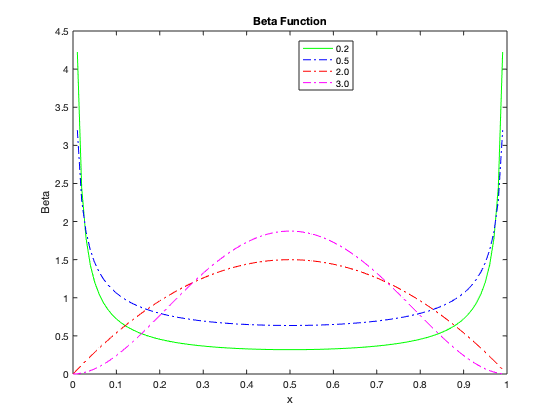

 

u = numel(x_range);

beta2_4 = zeros(1,u); 

for i = 1:u
    
    beta2_4(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end

%% SECOND PLOT

plot(x_range,beta2_1,'g')
hold on
plot(x_range,beta2_2,'-.b')
hold on
plot(x_range,beta2_3,'-.r')
hold on
plot(x_range,beta2_4,'-.m')
xlabel('x')
ylabel('Beta')
title('Beta Function')
legend('0.2','0.5', '2.0', '3.0', 'location',"best")

hold off





%%% THIRD PLOT

%%  ALPHA > BETA > 1





beta_alpha = 1.5

beta_alpha = 1.5000


beta_beta  = 1.1

beta_beta = 1.1000

 

u = numel(x_range);

beta3_1 = zeros(1,u); 

for i = 1:u
    
    beta3_1(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end





beta_alpha = 2

beta_alpha = 2


beta_beta  = 1

beta_beta = 1

 

u = numel(x_range);

beta3_2 = zeros(1,u); 

for i = 1:u
    
    beta3_2(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end




beta_alpha = 3

beta_alpha = 3


beta_beta  = 1

beta_beta = 1

 

u = numel(x_range);

beta3_3 = zeros(1,u); 

for i = 1:u
    
    beta3_3(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end





beta_alpha = 4

beta_alpha = 4


beta_beta  = 2

beta_beta = 2

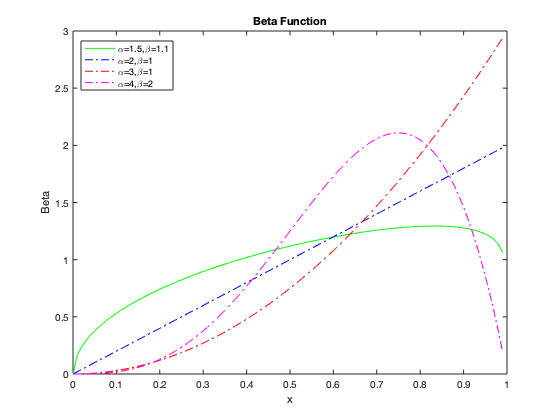

 

u = numel(x_range);

beta3_4 = zeros(1,u); 

for i = 1:u
    
    beta3_4(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end



%%  THIRD PLOT

plot(x_range,beta3_1,'g')
hold on
plot(x_range,beta3_2,'-.b')
hold on
plot(x_range,beta3_3,'-.r')
hold on
plot(x_range,beta3_4,'-.m')
xlabel('x')
ylabel('Beta')
title('Beta Function')
legend('\alpha=1.5,\beta=1.1','\alpha=2,\beta=1', '\alpha=3,\beta=1', '\alpha=4,\beta=2', 'location',"best")

hold off





%%%  ASYMMETRIC CASES (1<alpha<beta)



beta_alpha = 0.5

beta_alpha = 0.5000


beta_beta  = 0.1

beta_beta = 0.1000

 

u = numel(x_range);

beta4_1 = zeros(1,u); 

for i = 1:u
    
    beta4_1(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end




beta_alpha = 0.9

beta_alpha = 0.9000


beta_beta  = 0.1

beta_beta = 0.1000

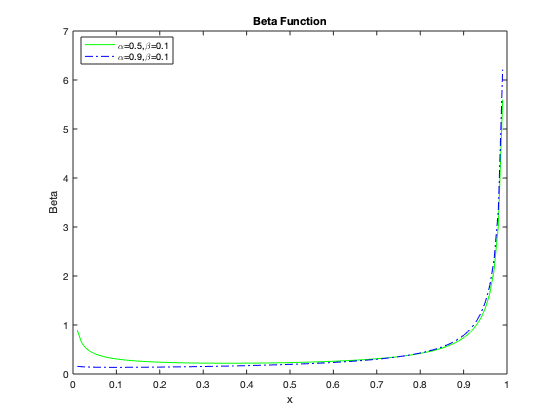

 

u = numel(x_range);

beta4_2 = zeros(1,u); 

for i = 1:u
    
    beta4_2(i)= betapdf(x_range(i),beta_alpha,beta_beta);
end








%%  FOURTH PLOT

plot(x_range,beta4_1,'g')
hold on
plot(x_range,beta4_2,'-.b')

xlabel('x')
ylabel('Beta')
title('Beta Function')
legend('\alpha=0.5,\beta=0.1','\alpha=0.9,\beta=0.1',  'location',"best")

hold off

# 2 B

%%﻿Calibration of LGD. Estimated Beta vs empirical distribution of LGD
LGD = [0;0.1;0.2;0.25;0.3;0.4;0.5;0.6;0.7;0.75;0.8;0.9;1];
PD = [0.01;0.02;0.1;0.25;0.1;0.02;0;0.02;0.1;0.25;0.1;0.02;0.01];


k = numel(PD)

k = 13


for i = 1:k
    s2(i)= PD(i)*LGD(i);
end

for i = 1:k
    h(i)= PD(i)*(LGD(i)-mean(LGD))^2;
end

O = transpose(s2(1:13))% A VECTOR OF PD AND LGD

O =          0
    0.0020
    0.0200
    0.0625
    0.0300
    0.0080
         0
    0.0120
    0.0700
    0.1875


A = transpose(h(1:13))

A =     0.0025
    0.0032
    0.0090
    0.0156
    0.0040
    0.0002
         0
    0.0002
    0.0040
    0.0156



t = table(LGD,PD,O,A)

t = 13×4 table
    LGD      PD       O          A    
    ____    ____    ______    ________

       0    0.01         0      0.0025
     0.1    0.02     0.002      0.0032
     0.2     0.1      0.02       0.009
    0.25    0.25    0.0625    0.015625
     0.3     0.1      0.03       0.004
     0.4    0.02     0.008      0.0002
     0.5       0         0           0
     0.6    0.02     0.012      0.0002
     0.7     0.1      0.07       0.004
    0.75    0.25    0.1875    0.015625
     0.8     0.1      0.08       0.009
     0.9    0.02     0.018      0.0032
       1    0.01      0.01      0.0025




z = sum(A)

z = 0.0691

m_lgd = sum(O)

m_lgd = 0.5000

s_lgd = sqrt(sum(A))

s_lgd = 0.2628

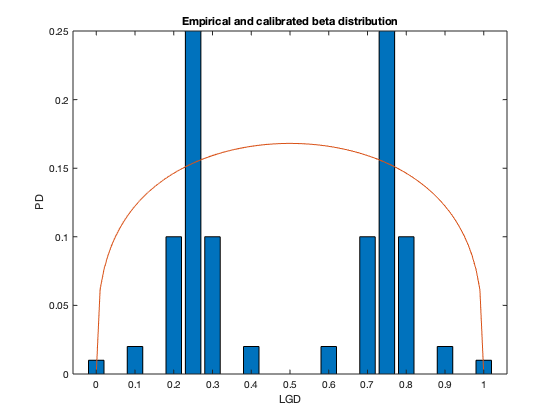




alph = (m_lgd^2*(1-m_lgd)/s_lgd^2)-m_lgd;
bet = ((m_lgd*(1-m_lgd)^2)/s_lgd^2)-(1-m_lgd);

x_rng = 0.00:0.01:1;

u = numel(x_rng);

beta_4 = zeros(1,u); 

for i = 1:u
    
    beta_4(i)= betapdf(x_rng(i),alph,bet);
end

bar(t.LGD,t.PD)

hold on

plot(x_rng,beta_4./7)

title('Empirical and calibrated beta distribution')
xlabel('LGD')
ylabel('PD')
hold off

2 C




lamda = [10,10,25,25,50,100,250,500,500,1000];

%%Finding the conditional probabilities

c_prob = zeros(1,numel(lamda))

c_prob =      0     0     0     0     0     0     0     0     0     0




for i = 1:numel(lamda)
    c_prob(i) = cdf("Exponential",5,lamda(i));
end






% MONTE CARLO STEP
% Obtaining the unconditional probabilities for
% 10000 samples of 10 portfolio each

samplesize = 10000

samplesize = 10000


m_unc_prob = zeros(numel(lamda),samplesize)

m_unc_prob =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

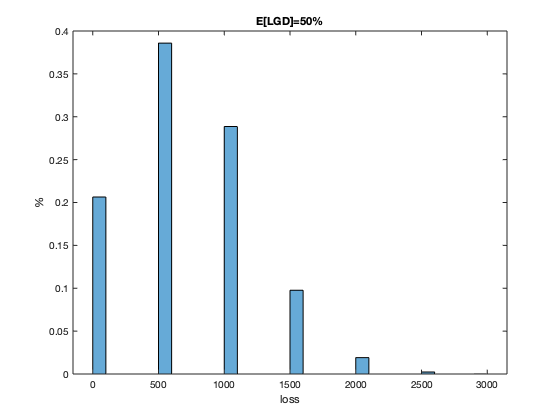

for i = 1:numel(lamda)
    for j = 1:samplesize
        m_unc_prob(i,j) = random('Binomial',1, c_prob(i));
        
    end
end




%(A) EADi =1000 ,  E[LGD] = 0.5

EAD = 1000;
LGD = 0.5;



loss_funtion = m_unc_prob.*EAD*LGD;



Loss_vector = sum(loss_funtion);


x = 0:500:4500;

histogram(Loss_vector,'Normalization','probability')


xlabel('loss')
ylabel('%')
title('E[LGD]=50%')

2C(ii)


%% MONTE CARLO SIMULATION OF LGD;using inverse transform method

 

LGD = [0;0.1;0.2;0.25;0.3;0.4;0.5;0.6;0.7;0.75;0.8;0.9;1];






LGD_E = zeros(numel(lamda),samplesize)

LGD_E =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

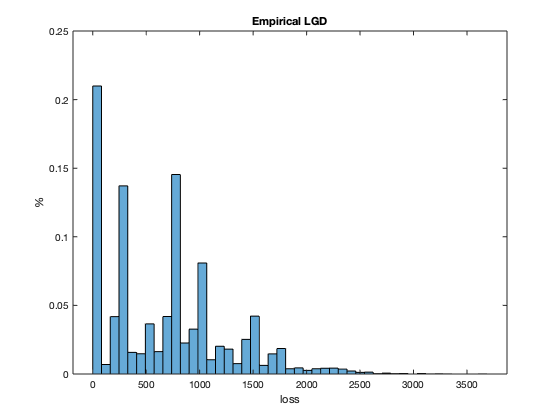

for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_E(i,j) = LGD_matrix(LGD,PD);
        
    end 
end




loss_funtion2 = m_unc_prob.*LGD_E*EAD;

Loss_vector2 = sum(loss_funtion2);

histogram(Loss_vector2,45,'Normalization','probability')


xlabel('loss')
ylabel('%')
title('Empirical LGD')

2C(iii)

 %%SIMULATING THE LGD FROM A BETA DISTRIBUTION




% x = repmat(LGD_Beta,1,size(m_unc_prob,10000));
% loss_funtion3 = (x.*m_unc_prob).*EAD;


LGD_Beta = zeros(numel(lamda),samplesize)

LGD_Beta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

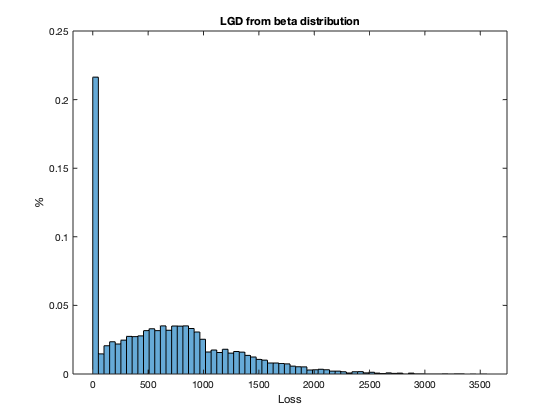

for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_Beta(i,j) =betarnd(alph,bet);
        
    end 
end



loss_funtion3 = m_unc_prob.*LGD_Beta*EAD;

loss_vector3 = sum(loss_funtion3);



histogram(loss_vector3,70,'Normalization','probability')

xlabel('Loss')
ylabel('%')
title('LGD from beta distribution')

# 3

% PLOTTING THE HAZARD FUNCTIONS UNDER THE PIECEWISE EXPONENTIAL
syms t_yr
l1 = piecewise(0<t_yr<1,1,1<t_yr<2,1.5,2<t_yr<3,2,3<t_yr<4,2.5,t_yr>4,3);

l2 = piecewise(0<t_yr<=1,10,1<t_yr<=2,7,2<t_yr<=5,5,5<t_yr<=7,4.5,t_yr>7,6);

l3 = piecewise(t_yr>0,4)

$$l3 = \left\{ \begin{array}{cl} 4 & \text{ if }0<t_{\mathrm{yr}} \end{array}\right.$$

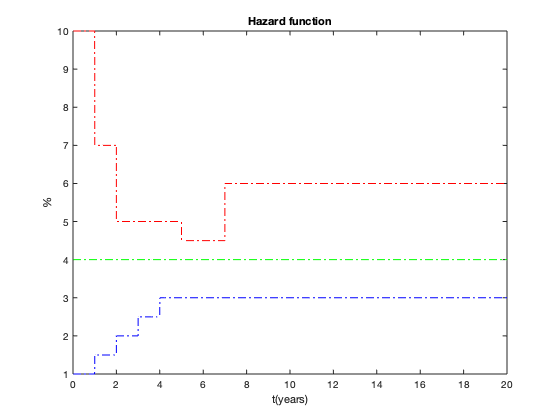


fplot(l1,[0,20],"-.b")
hold on
fplot(l2,[0,20],"-.r")
hold on
fplot(l3,[0,20],"-.g")
title("Hazard function")
ylabel('%')
xlabel('t(years)')
hold off

% PLOTTING THE SURVIVAL FUNCTIONS


a = 0:0.01:20

a =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



s1= zeros(1,numel(a));

for i = 1:numel(a)
    if a(i)<=1
        s1(i)= exp(-0.01*(a(i)));
    else
        if a(i)>1 && a(i)<=2
            s1(i) =exp(-0.01-0.015*(a(i)-1));
        else
            if a(i)>2 && a(i)<=3
                s1(i) =exp(-0.025-0.02*(a(i)-2));
            else
                if a(i)>3 && a(i)<=4
                    s1(i) =exp(-0.045-0.025*(a(i)-3));
                else
                    if a(i)>4 
                        s1(i) =exp(-0.07-0.03*(a(i)-4));
                    end
                end
            end
        end
    end
end


s2= zeros(1,numel(a));

for i = 1:numel(a)
    if a(i)<=1
        s2(i)= exp(-0.1*(a(i)));
    else
        if a(i)>1 && a(i)<=2
            s2(i) =exp(-0.1-0.07*(a(i)-1));
        else
            if a(i)>2 && a(i)<=5
                s2(i) =exp(-0.17-0.05*(a(i)-2));
            else
                if a(i)>5 && a(i)<=7
                    s2(i) =exp(-0.32-0.045*(a(i)-5));
                else
                    if a(i)>7 
                        s2(i) =exp(-0.365-0.06*(a(i)-7));
                    end
                end
            end
        end
    end
end






s3 = zeros(1,numel(a))

s3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


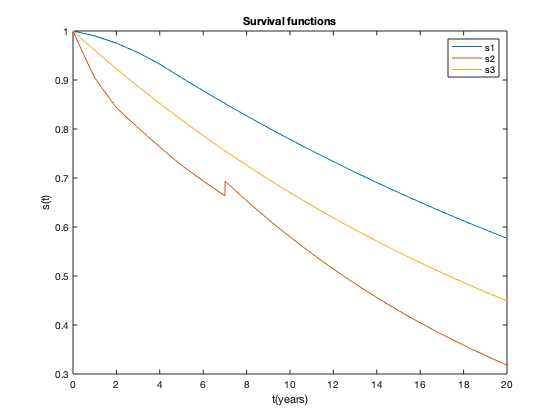


for i = 1:numel(a)
    s3(i)= exp(-0.04*(a(i)));
end


plot(a,s1)
hold on
plot(a,s2)
hold on
plot(a,s3)
hold off
title("Survival functions")
xlabel("t(years)")
ylabel("s(t)")
legend("s1","s2","s3")



f1= zeros(1,numel(a));

for i = 1:numel(a)
    if a(i)<=1
        f1(i)= 0.01*exp(-0.01*(a(i)));
    else
        if a(i)>1 && a(i)<=2
            f1(i) =0.015*exp(-0.01-0.015*(a(i)-1));
        else
            if a(i)>2 && a(i)<=3
                f1(i) =0.02*exp(-0.025-0.02*(a(i)-2));
            else
                if a(i)>3 && a(i)<=4
                    f1(i) =0.025*exp(-0.045-0.025*(a(i)-3));
                else
                    if a(i)>4 
                        f1(i) =0.03*exp(-0.07-0.03*(a(i)-4));
                    end
                end
            end
        end
    end
end


f2= zeros(1,numel(a));

for i = 1:numel(a)
    if a(i)<=1
        f2(i)= 0.1*exp(-0.1*(a(i)));
    else
        if a(i)>1 && a(i)<=2
            f2(i) =0.07*exp(-0.1-0.07*(a(i)-1));
        else
            if a(i)>2 && a(i)<=5
                f2(i) =0.05*exp(-0.17-0.05*(a(i)-2));
            else
                if a(i)>5 && a(i)<=7
                    f2(i) =0.045*exp(-0.32-0.045*(a(i)-5));
                else
                    if a(i)>7 
                        f2(i) =0.06*exp(-0.365-0.06*(a(i)-7));
                    end
                end
            end
        end
    end
end




f3 = zeros(1,numel(a))

f3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


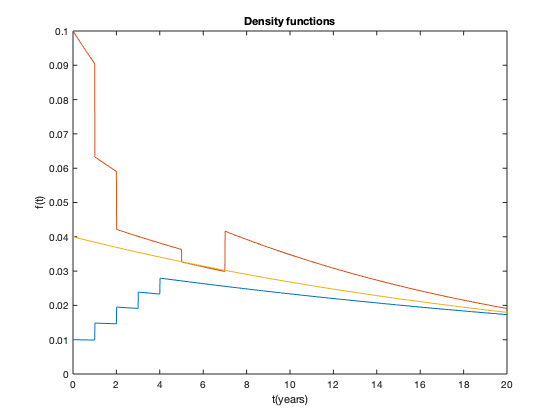


for i = 1:numel(a)
    f3(i)= 0.04*exp(-0.04*(a(i)));
end


plot(a,f1)
hold on
plot(a,f2)
hold on
plot(a,f3)
hold off
title("Density functions")
xlabel("t(years)")
ylabel("f(t)")

3.2


% ﻿Estimation of survival functions from default data
 
DD = [3,6,9,12,15,18,21,24]/12 ; %Default dates
D = [2,5,9,12,16,20,25,29] ;% defaults
s = 1 - (D)/1000 ; %the survival probabilities



% the least squares estimator for the parameter of the exponontial function

fun = @(d)exp(-d*DD) - s ;
lam = lsqnonlin(fun , 1.2) ;


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>





%% Estimating the parameters of exponential distribution

lamda = zeros(1, numel(s)) ;
lamda(1) = -log(s(1))/(DD(1)-0) ;
for i = 2:numel(s)
   lamda(i) = -log((s(i))/(s(i-1)))/(DD(i)-DD(i-1)) ;
end




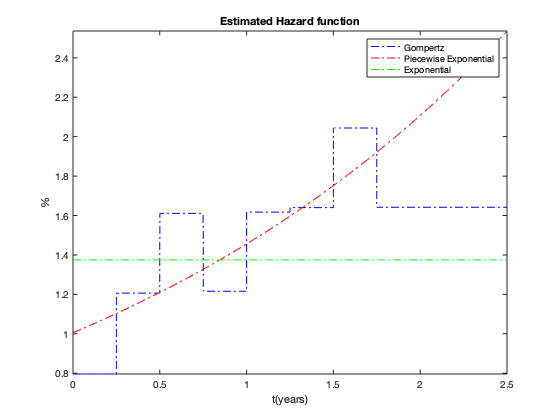


%%Plotting the hazard functions

x = linspace(0,2.5);
h2 = (exp(x.*0.370)).*(2.718*0.370);
 
syms t_yr

h1 = piecewise(0<t_yr<0.25,0.796,0.25<t_yr<0.5,1.206,0.5<t_yr<0.75, 1.611,0.75<t_yr<1,1.216, ...
    1<t_yr<1.25,1.617,1.25<t_yr<1.5,1.640,1.5<t_yr<1.75,2.044,1.75<t_yr,1.642);


h3 = piecewise(t_yr>0,1.375);

fplot(h1,[0,2.5],"-.b")
hold on
plot(x,h2,"-.r")
hold on
fplot(h3,[0,2.5],"-.g")
title("Estimated Hazard function")
ylabel('%')
xlabel('t(years)')
legend( "Gompertz","Piecewise Exponential","Exponential")
hold off

3C

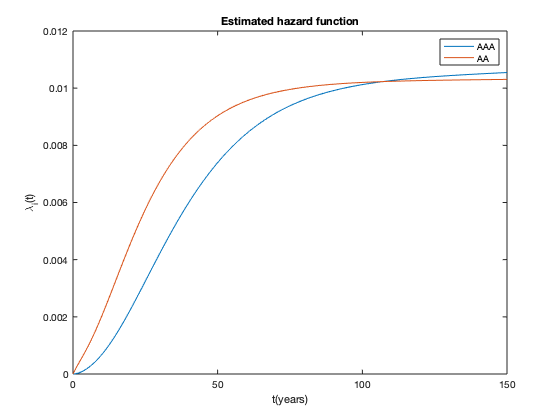


% ﻿Estimation of survival functions from a credit migration matrix

P1 = [0.9288 , 0.0650 , 0.0056 , 0.0006 , 0.0006, 0.0000 , 0.0000 , 0.0000; 0.0063, 0.9187 , 0.0664 , 0.0065 ...
    0.0006, 0.0011 , 0.0004 , 0.0000 ; 0.0008 , 0.0226 , 0.9166 , 0.0511 , 0.0061 , 0.0023 , 0.0001 , 0.0004 ; ...
    0.0005 , 0.0027 , 0.0584 , 0.8774 , 0.0474 , 0.0098 , 0.0016 , 0.0022 ; 0.0004 , 0.0011 , 0.0064 , 0.0785 ,...
    0.8114 , 0.0827 , 0.0089 , 0.0106 ; 0.0000 , 0.0011 , 0.0030 , 0.0042 , 0.0675 , 0.8307 , 0.0386 , 0.0549 ;...
    0.0019 , 0.0000 , 0.0038 , 0.0075 , 0.0244 , 0.1203 , 0.6071 , 0.2350 ; 0.0000 , 0.0000 , 0.0000 , 0.0000 , 0.0000 , 0.0000 , ...
    0.0000 , 1.0000];


%% Generating the credit transition matrix

m = 0:1:150 ;      %%Matrix dimension

Def_P = cell(numel(m),1) ;
for i=1:numel(m)
    Def_P{i} = P1^i;
end


%% AAA rated tranistion matrix(Default probability)

Def_P_AAA = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_AAA(i) = log((1-Def_P{i-1}(1,8))/(1-Def_P{i}(1,8))) ;
end


%% AA rated default probability

Def_P_AA = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_AA(i) = log((1-Def_P{i-1}(2,8))/(1-Def_P{i}(2,8))) ;
end


plot(m,Def_P_AAA)
hold on
plot(m,Def_P_AA) 
xlabel("t(years)")
ylabel("\lambda_{i}(t)")
legend("AAA","AA")
title("Estimated hazard function")
hold off

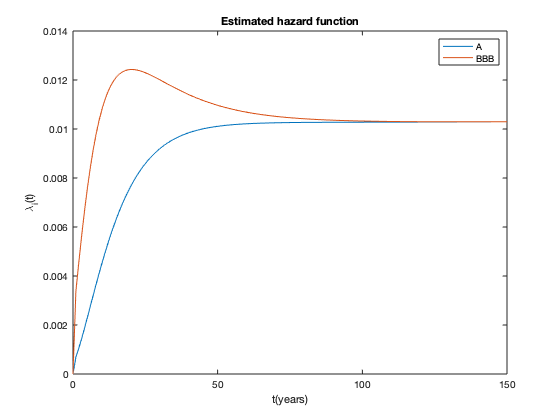



%% A rated tranistion matrix(Default probability)

Def_P_A = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_A(i) = log((1-Def_P{i-1}(3,8))/(1-Def_P{i}(3,8))) ;
end


%% BBB rated default probability

Def_P_BBB = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_BBB(i) = log((1-Def_P{i-1}(4,8))/(1-Def_P{i}(4,8))) ;
end


plot(m,Def_P_A)
hold on
plot(m,Def_P_BBB)
xlabel("t(years)")
ylabel("\lambda_{i}(t)")
legend("A","BBB")
title("Estimated hazard function")
hold off

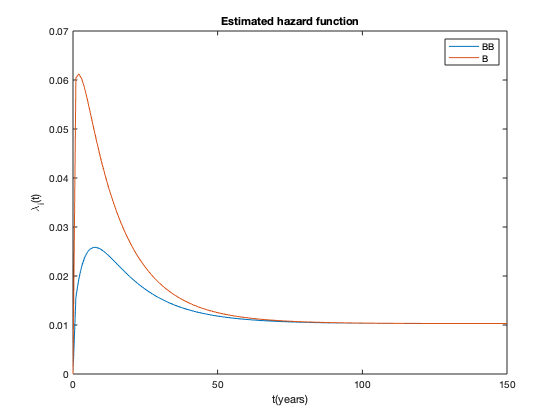



%% BB rated tranistion matrix(Default probability)

Def_P_BB = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_BB(i) = log((1-Def_P{i-1}(5,8))/(1-Def_P{i}(5,8))) ;
end


%% B rated default probability

Def_P_B = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_B(i) = log((1-Def_P{i-1}(6,8))/(1-Def_P{i}(6,8))) ;
end


plot(m,Def_P_BB)
hold on
plot(m,Def_P_B)
xlabel("t(years)")
ylabel("\lambda_{i}(t)")
legend("BB","B")
title("Estimated hazard function")
hold off

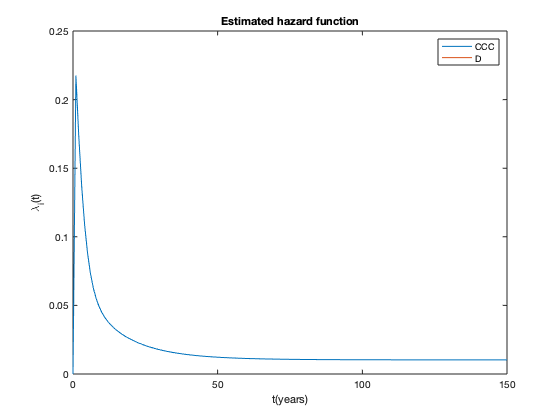




%% CCC rated tranistion matrix(Default probability)

Def_P_CCC = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_CCC(i) = log((1-Def_P{i-1}(7,8))/(1-Def_P{i}(7,8))) ;
end


%% D rated default probability

Def_P_D = zeros(numel(Def_P,1)) ;
for i = 2:numel(Def_P)
    Def_P_D(i) = log((1-Def_P{i-1}(8,8))/(1-Def_P{i}(8,8))) ;
end


plot(m,Def_P_CCC)
hold on
plot(m,Def_P_D)
xlabel("t(years)")
ylabel("\lambda_{i}(t)")
legend("CCC","D")
title("Estimated hazard function")
hold off

A = logm(P1)*10000 ;
b = zeros(8) ;
c = zeros(1,8) ;
A_1 = zeros(8) ;
for i=1:8
    for j=1:8
     if i~=j
         b(i,j) = min(A(i,j),0) ;
         A_1(i,j) = max(A(i,j),0) ;
         c = sum(b,2) ;
    else 
        A_1(i,j) = A(i,j) + c(i) ;%+ sum(min(A(i,j),0),1) ;
     end
    end 
end

A_1

A_1 = 	1.0e+03 *

   -0.7410    0.7034    0.0352    0.0030    0.0066         0         0    0.0000
    0.0679   -0.8593    0.7225    0.0516    0.0026    0.0110    0.0049         0
    0.0077    0.2456   -0.8982    0.5677    0.0540    0.0206         0    0.0028
    0.0051    0.0215    0.6502   -1.3523    0.5576    0.0856    0.0161    0.0162
    0.0042    0.0102    0.0417    0.9306   -2.1597    0.9996    0.0973    0.0760
         0    0.0118    0.0301    0.0087    0.8183   -1.9377    0.5392    0.5295
    0.0251         0    0.0441    0.0849    0.2720    1.6787   -5.0459    2.9411
         0         0         0         0         0         0         0         0


3D -SECOND METHOD


%% ISRAEL'S SECOND METHOD FOR MARKOV GENERATORS

hh =zeros(8) ;
h1 = zeros(8) ;
for i = 1:8
    for j=1:8 
        if i~=j 
            hh(i,j) = max(A(i,j),0) ;
            h1(i,j) = max(-A(i,j),0) ;
            h_1 = sum(hh,2) ;
            h_h = sum(h1,2) ;
        end
    end
end
            
G_i = abs(diag(A))

G_i = 	1.0e+03 *

    0.7410
    0.8593
    0.8982
    1.3523
    2.1597
    1.9368
    5.0430
         0


B_i = h_h

B_i =     1.0088
    1.1298
    0.2208
         0
         0
    0.8355
    2.8865
         0





A3 = zeros(8) ;
for i = 1:8
    for j = 1:8
        if i~=j
            A3(i,j) = max(A(i,j),0) ;
        %else 
            %if G_i(i) == 0
               % A3(i,j) = A(i,j) ;
            else 
                A3(i,j) = A(i,j); %- B_i(i)*(abs ;
            %end
        end
    end
end

 
A4 = zeros(8) ;
for i = 1:8
    for j = 1:8
        if G_i(i) == 0
            A4(i,j) = A3(i,j) ;
        else
            A4(i,j) = A3(i,j)- B_i(i) * (abs(A3(i,j)))/G_i(i) ;
        end
    end
end








# 4

% SIMULATNG FROM INDEPENDENT GAUSSIAN RVs (n+1)
%clear ; clc ; close all


EAD = 1000;
LGD = [0;0.1;0.2;0.25;0.3;0.4;0.5;0.6;0.7;0.75;0.8;0.9;1] ;
PD = [0.01;0.02;0.1;0.25;0.1;0.02;0;0.02;0.1;0.25;0.1;0.02;0.01] ;






%% simulating the basel copula function


%rho =0.00
samplesize =10000

samplesize = 10000

lamda = [10,10,25,25,50,100,250,500,500,1000]/10000;

rho_cop1 = 0.00;
unif1 = zeros(10,1);



%%setting the tau values to the inverse survival functions

tau_cop1 = zeros(10,1);
MC_tau1 = zeros(numel(lamda),samplesize);

for j = 1:samplesize
    n = 11 ;
    z1 = normrnd(0,1,n,1);
    for i = 1:10
        unif1(i) = normcdf(sqrt(rho_cop1)*z1(1) + sqrt(1-rho_cop1)*z1(i+1));
        tau_cop1(i) = -(log(unif1(i)))/lamda(i);
    end
    MC_tau1(:,j) = tau_cop1;
end
%% modelling the probability of default


PD_G1 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j= 1:samplesize
        if MC_tau1(i,j)<=5
        PD_G1(i,j)= 1 ;
        else 
         PD_G1(i,j) = 0 ;
        end
    end
end



%%Modelling the LGD


LGD_G1 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_G1(i,j) = LGD_matrix(LGD,PD);
        
    end 
end

Loss_GC1 = sum(PD_G1.*LGD_G1*EAD);
VaR_1 = prctile(Loss_GC1,99)

VaR_1 = 2000

ES_1 = mean(Loss_GC1(Loss_GC1>VaR_1))

ES_1 = 2.3216e+03

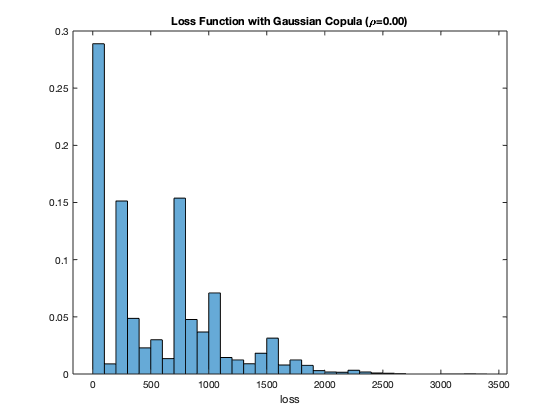


histogram(Loss_GC1,'Normalization','probability')

title("Loss Function with Gaussian Copula (\rho=0.00)")
xlabel("loss")

%ylabel("Frequency")

Rho = 0.2

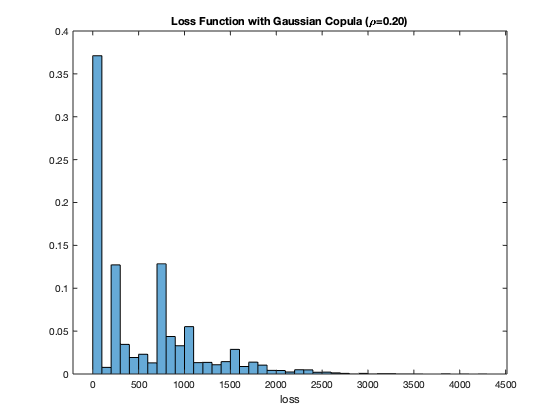

rho_cop2 = 0.20;
unif2 = zeros(10,1);

% for i = 1:10
%     unif(i) = normcdf(sqrt(rho_cop)*z(1) + sqrt(1-rho_cop)*z(i+1));
% end

%%setting the tau values to the inverse survival functions

tau_cop2 = zeros(10,1);
MC_tau2 = zeros(numel(lamda),samplesize);

for j = 1:samplesize
    n = 11 ;
    z2 = normrnd(0,1,n,1);
    for i = 1:10
        unif2(i) = normcdf(sqrt(rho_cop2)*z2(1) + sqrt(1-rho_cop2)*z2(i+1));
        tau_cop2(i) = -(log(unif2(i)))/lamda(i);
    end
    MC_tau2(:,j) = tau_cop2;
end
%% modelling the probability of default


PD_G2 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j= 1:samplesize
        if MC_tau2(i,j)<=5
        PD_G2(i,j)= 1 ;
        else 
         PD_G2(i,j) = 0 ;
        end
    end
end



%%Modelling the LGD


LGD_G2 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_G2(i,j) = LGD_matrix(LGD,PD);
        
    end 
end

Loss_GC2 = sum(PD_G2.*LGD_G2*EAD);
VaR_2 = prctile(Loss_GC2,99);
ES_2 = mean(Loss_GC2(Loss_GC2>VaR_2));


histogram(Loss_GC2,'Normalization','probability')

title("Loss Function with Gaussian Copula (\rho=0.20)")
xlabel("loss")

%ylabel("Frequency")

Rho = 0.5

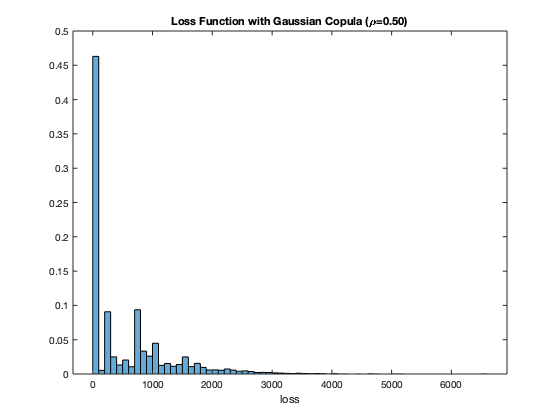

rho_cop3 = 0.50;
unif3 = zeros(10,1);

% for i = 1:10
%     unif(i) = normcdf(sqrt(rho_cop)*z(1) + sqrt(1-rho_cop)*z(i+1));
% end

%%setting the tau values to the inverse survival functions

tau_cop3 = zeros(10,1);
MC_tau3 = zeros(numel(lamda),samplesize);

for j = 1:samplesize
    n = 11 ;
    z3 = normrnd(0,1,n,1);
    for i = 1:10
        unif3(i) = normcdf(sqrt(rho_cop3)*z3(1) + sqrt(1-rho_cop3)*z3(i+1));
        tau_cop3(i) = -(log(unif3(i)))/lamda(i);
    end
    MC_tau3(:,j) = tau_cop3;
end
%% modelling the probability of default


PD_G3 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j= 1:samplesize
        if MC_tau3(i,j)<=5
        PD_G3(i,j)= 1 ;
        else 
         PD_G3(i,j) = 0 ;
        end
    end
end



%%Modelling the LGD


LGD_G3 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_G3(i,j) = LGD_matrix(LGD,PD);
        
    end 
end

Loss_GC3 = sum(PD_G3.*LGD_G3*EAD);

%% VAR  & ES CALCULATIONS


VaR_3 = prctile(Loss_GC3,99);
ES_3 = mean(Loss_GC3 (Loss_GC3>VaR_3));


histogram(Loss_GC3,'Normalization','probability')

title("Loss Function with Gaussian Copula (\rho=0.50)")
xlabel("loss")

%ylabel("Frequency")


Rho =0.9

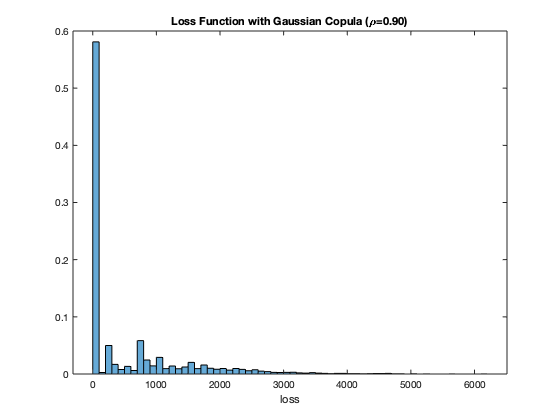

rho_cop4 = 0.90;
unif4 = zeros(10,1);


%%setting the tau values to the inverse survival functions

tau_cop4 = zeros(10,1);
MC_tau4 = zeros(numel(lamda),samplesize);

for j = 1:samplesize
    n = 11 ;
    z4 = normrnd(0,1,n,1);
    for i = 1:10
        unif4(i) = normcdf(sqrt(rho_cop4)*z4(1) + sqrt(1-rho_cop4)*z4(i+1));
        tau_cop4(i) = -(log(unif4(i)))/lamda(i);
    end
    MC_tau4(:,j) = tau_cop4;
end
%% modelling the probability of default


PD_G4 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j= 1:samplesize
        if MC_tau4(i,j)<=5
        PD_G4(i,j)= 1 ;
        else 
         PD_G4(i,j) = 0 ;
        end
    end
end



%%Modelling the LGD


LGD_G4 = zeros(numel(lamda),samplesize);
for i = 1:numel(lamda)
    for j = 1:samplesize
        LGD_G4(i,j) = LGD_matrix(LGD,PD);
        
    end 
end

Loss_GC4 = sum(PD_G4.*LGD_G4*EAD);

%% VAR  & ES CALCULATIONS


VaR_4 = prctile(Loss_GC4,99);
ES_4 = mean(Loss_GC4 (Loss_GC4>VaR_3));



histogram(Loss_GC4,'Normalization','probability')

title("Loss Function with Gaussian Copula (\rho=0.90)")
xlabel("loss")

%ylabel("Frequency")




# BIANCHETTI's PART


% CONTRACT FEATURES


sigma = 0.2 ;        %Volatility
mat = 1.5  ;        %Maturity
sp = 6;
rf = 0.02;
S0= 100 ;  %Spot price
q          = 0;

% ADDITIONAL INFORMATION


R_B = 0.4  ;  %Bank's recovery rate
LGD_B = 1-R_B;
R_C = 0.5   ; %Counterparty's recovery rate
LGD_C = 1-R_C;

CSb = 0.005 ;  %Credit spread of bank
CSc = 0.01 ;  %Credit spread of counterparty




### QUESTION 1



% RISK-FREE MARK TO MARKET

t_p = 0:0.1:mat;  %Partition on the maturity [0,T]

F0 = S0*exp(rf*mat);

MTM_BS = S0 - F0*exp(-rf*mat);






% CALCULATING THE DEFAULT PROBABILITY

% BANK PD

P_def_B = zeros(numel(t_p,1))

P_def_B = 0


for i = 1:numel(t_p)
    P_def_B(i)= 1- exp(-CSb*t_p(i)/(1-R_B));
end


% COUNTERPARTY PD

P_def_C = zeros(numel(t_p,1));

for i = 1:numel(t_p)
    P_def_C(i)= 1- exp(-CSc*t_p(i)/(1-R_C));
end



% EVALUATING THE BLACK SCHOLES

K = zeros(numel(t_p,1));
Call = zeros(numel(t_p,1)); 
CVA_A = zeros(numel(t_p,1));
DVA_A = zeros(numel(t_p,1));

for i=1:numel(t_p)
%     F(i) = S0*exp((rf-q)*(t_p(i)));
    K(i) = F0*exp(-rf*t_p(i));
    Call(i) = blsprice(S0, K(i), rf,mat, sigma);
    CVA_A(i) =-LGD_C*P_def_C(i)*(1-P_def_B(i))*Call(i);
    DVA_A(i) =-LGD_B*P_def_B(i)*(1-P_def_C(i))*(-Call(i));
end

CVA_TOT = sum(CVA_A)  %first to default CVA by analytical

CVA_TOT = -1.2606

DVA_TOT = sum(DVA_A)  %first to default DVA by analytical

DVA_TOT = 0.6265




% CALCULATING THE TOTAL FAIR VALUE

Fair_value = MTM_BS+CVA_TOT+DVA_TOT

Fair_value = -0.6341


% MONTE CARLO APPROACH

MC_n = 1000

MC_n = 1000


step = 252+126; % number of step/days [because 1.5 years]
dt = 1/252;
t_MC = (0:step)'*dt; % time-step

S_t = GBM_MC(MC_n,step,dt,S0,rf,sigma);

MTM_MC = (S_t - F0*exp(-rf*flip(t_MC)));




% CRR METRICS FOR MONTE CARLO



MTM_rf_MC = zeros(step+1,1);
E_MC = zeros(step+1,MC_n);
NE_MC = zeros(step+1,MC_n);
% PFE_MC = zeros(step+1,1);
% PFNE_MC = zeros(step+1,1);
% MPFE_t_MC = zeros(step+1,1);
EE_MC = zeros(step+1,1);
ENE_MC = zeros(step+1,1);
% EEE_MC = zeros(step+1,1);
EPE_t_MC = zeros(step+1,1);
% EEPE_t_MC = zeros(step+1,1);
DF_MC = zeros(step+1,1);
CVA_MC = zeros(step+1,1);
DVA_MC = zeros(step+1,1);
MTM_risky_MC = zeros(1,step+1);

for i=(1:step+1)
MTM_rf_MC(i) = sum(MTM_MC(i,:))/MC_n;

E_MC(i,:) = max(MTM_MC(i,:),0) ; % Positive Exposure 
NE_MC(i,:) = min(MTM_MC(i,:),0) ; % Negative Exposure 

EE_MC(i) = sum(E_MC(i,:))/MC_n; % Positive Expected Exposure
ENE_MC(i) = sum(NE_MC(i,:))/MC_n; % Expected Negative Exposure


PFE_MC(i) = prctile(E_MC(i,:),99); % Potential Future Positive Exposure
PFNE_MC(i) = -prctile(abs(NE_MC(i,:)),99); % Potential Future Negative Exposure
MPFE_t_MC(i)=max(PFE_MC); % Maximum Potential Future Exposure tyme by time

EPE_t_MC(i)=(1/mat)*trapz(EE_MC,t_MC); % Expected Positive Exposure tyme by tyme

EEE_MC(i) = max(EE_MC); % Effective expected exposure

EPE_t_MC(i)=(1/mat)*trapz(EE_MC,t_MC); % Expected Positive Exposure tyme by tyme
% EEPE_t_MC(i) = (1/mat)*trapz(EEE_MC,t_MC); % Effective Expected Positive Exposure tyme by tyme


DF_MC(i) = exp(-rf*t_MC(i));
PD_C_MC = 1- exp(((-CSc*dt))/(1-R_C));
PD_B_MC = 1- exp(((-CSb*dt))/(1-R_B));
CVA_MC(i) = -LGD_C*PD_C_MC*(1-PD_B_MC)*EE_MC(i)*DF_MC(i);
DVA_MC(i) = -DF_MC(i)*LGD_B*ENE_MC(i)*PD_B_MC*(1-PD_C_MC);

MTM_risky_MC(i) = MTM_rf_MC(i) + CVA_MC(i) + DVA_MC(i);

end

CVA_TOT_MC=sum(CVA_MC);
DVA_TOT_MC=sum(DVA_MC);


EPE_MC = (1/mat)*trapz(EE_MC,t_MC); % Expected Positive Exposure

MPFE_MC = max(PFE_MC); % Maximum Potential Future Exposure

EEPE_MC = (1/mat)*trapz(EEE_MC,t_MC); % Effective Expected Positive Exposure





% ﻿Sensitivity of ftdCVA and ftdDVA to +1bps change of CSB and CSC


CSb_new = 0.005 +0.0001 ;  %Credit spread of bank-new
CSc_new = 0.01 +0.0001 ;  %Credit spread of counterparty-new

% CALCULATING THE DEFAULT PROBABILITY

% BANK PD

P_def_B_new = zeros(numel(t_p,1));

for i = 1:numel(t_p)
    P_def_B_new(i)= (1- exp(-CSb_new*t_p(i)))/(1-R_B);
end


% COUNTERPARTY PD

P_def_C_new = zeros(numel(t_p,1));

for i = 1:numel(t_p)
    P_def_C_new(i)= (1- exp(-CSc_new*t_p(i)))/(1-R_C);
end





% EVALUATING THE BLACK SCHOLES

K_new = zeros(numel(t_p,1));
Call_new = zeros(numel(t_p,1)); 
CVA_A_new = zeros(numel(t_p,1));
DVA_A_new = zeros(numel(t_p,1));

for i=1:numel(t_p)
%     F(i) = S0*exp((rf-q)*(t_p(i)));
    K_new(i) = F0*exp(-rf*t_p(i));
    Call_new(i) = blsprice(S0, K(i), rf,t_p(i), sigma);
    CVA_A_new(i) =-LGD_C*P_def_C_new(i)*(1-P_def_B_new(i))*Call_new(i);
    DVA_A_new(i) =-LGD_B*P_def_B_new(i)*(1-P_def_C_new(i))*(-Call_new(i));
end

CVA_TOT_new = sum(CVA_A_new)  %first to default CVA by analytical

CVA_TOT_new = -1.0109

DVA_TOT_new = sum(DVA_A_new)  %first to default DVA by analytical

DVA_TOT_new = 0.5051


% MONTE CARLO APPROACH - sensitivity

MTM_rf_MC_new = zeros(step+1,1);

MTM_rf_MC = zeros(step+1,1);
E_MC = zeros(step+1,MC_n);
NE_MC = zeros(step+1,MC_n);
% PFE_MC = zeros(step+1,1);
% PFNE_MC = zeros(step+1,1);
% MPFE_t_MC = zeros(step+1,1);
EE_MC = zeros(step+1,1);
ENE_MC = zeros(step+1,1);
% EEE_MC = zeros(step+1,1);
EPE_t_MC = zeros(step+1,1);
% EEPE_t_MC = zeros(step+1,1);
DF_MC = zeros(step+1,1);
CVA_MC_new = zeros(step+1,1);
DVA_MC_new = zeros(step+1,1);
MTM_risky_MC = zeros(1,step+1);

for i=(1:step+1)
    
MTM_rf_MC(i) = sum(MTM_MC(i,:))/MC_n;

E_MC(i,:) = max(MTM_MC(i,:),0) ; % Positive Exposure 
NE_MC(i,:) = min(MTM_MC(i,:),0) ; % Negative Exposure 

EE_MC(i) = sum(E_MC(i,:))/MC_n; % Positive Expected Exposure
ENE_MC(i) = sum(NE_MC(i,:))/MC_n; % Expected Negative Exposure



DF_MC(i) = exp(-rf*t_MC(i));
PD_C_MC_new = 1- exp(((-CSc_new*dt))/(1-R_C));
PD_B_MC_new = 1- exp(((-CSb_new*dt))/(1-R_B));
CVA_MC_new(i) = -LGD_C*PD_C_MC_new*(1-PD_B_MC_new)*EE_MC(i)*DF_MC(i);
DVA_MC_new(i) = -DF_MC(i)*LGD_B*ENE_MC(i)*PD_B_MC_new*(1-PD_C_MC_new);

MTM_risky_MC(i) = MTM_rf_MC(i) + CVA_MC_new(i) + DVA_MC_new(i);

end

CVA_TOT_MC_new=sum(CVA_MC_new);
DVA_TOT_MC_new=sum(DVA_MC_new);



% PERCENTAGE GHANGE IN ftdCVA AND ftdDVA for +1bp change in CS

CVA_change_A = (CVA_TOT_new-CVA_TOT)/0.0001

CVA_change_A = 2.4967e+03

DVA_change_A = (DVA_TOT_new-DVA_TOT)/0.0001

DVA_change_A = -1.2133e+03

CVA_change_MC = (CVA_TOT_MC_new-CVA_TOT_MC)/0.0001

CVA_change_MC = -9.2857

DVA_change_MC = (DVA_TOT_MC_new-DVA_TOT_MC)/0.0001

DVA_change_MC = 10.0137

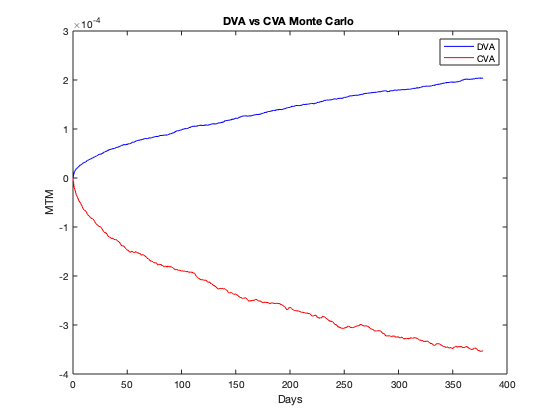

% PLOTS

% Evolution of CVA and DVA by the analytical approach

x = 0:1:378;

figure
plot(x,DVA_MC, 'blue')
title('DVA vs CVA Monte Carlo ')
xlabel('Days')
ylabel('MTM')
hold on
plot(x,CVA_MC,'red')
legend({'DVA','CVA'})
hold off

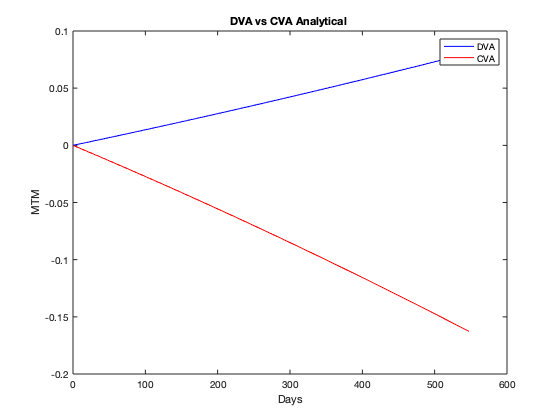



figure
figure
plot(t_p*(365),DVA_A, 'blue')
title('DVA vs CVA Analytical ')
xlabel('Days')
ylabel('MTM')
hold on
plot(t_p*(365),CVA_A,'red')
legend({'DVA','CVA'})

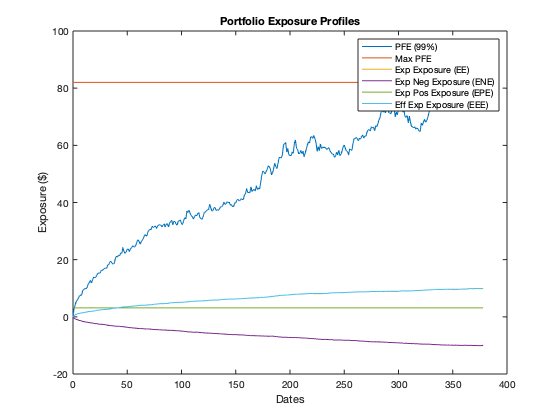


figure;
plot(x,PFE_MC, ...
    x,MPFE_MC * ones(step+1,1), ...
    x,EE_MC, ...
    x,ENE_MC, ...
    x,EPE_MC * ones(step+1,1), ...
    x,EEE_MC);
%     x,EEPE_MC * ones(n_Step+1,1));
    
legend({'PFE (99%)','Max PFE','Exp Exposure (EE)','Exp Neg Exposure (ENE)','Exp Pos Exposure (EPE)', ...
    'Eff Exp Exposure (EEE)'})

title('Portfolio Exposure Profiles');
ylabel('Exposure ($)')
xlabel('Dates')